addpath('C:\Users\feder\Dropbox\Tesi Finotto\matlab\code');
addpath('C:\Users\feder\Dropbox\Tesi Finotto\matlab\code\Datasets\');
addpath('C:\Users\feder\Dropbox\Tesi Finotto\matlab\code\functions\');

Importo dataset e definisco le variabili

TrainSetting.nTestPattern = 0;
if(TrainSetting.nTrainPattern~=0)
    maxNetTrainSize = dataset.train(TrainSetting.nTrainPattern).size;
    for i = 1:length(dataset.test)
        if (dataset.test(i).size < maxNetTrainSize)
            TrainSetting.nTestPattern = i;
        else
            break;
        end
    end
end
XTest = {dataset.test.input};
TTest = {dataset.test.output};
esempi = 1;
if(TrainSetting.nTestPattern~=0)
    XTest = XTest(1:TrainSetting.nTestPattern);
    TTest = TTest(1:TrainSetting.nTestPattern);
end
nRNA = length(XTest);
immagini = struct("imgX",{},"imgT",{},"imgY",{},"imgCompare",{},"X",{},"Y",{},"T",{});
randomized = randperm(nRNA);

Prendo N immagini dal dataset di test e le elaboro in modo che siano visivamente significative

for i=1:esempi  
    NTest = randomized(i);
    L = length(XTest{NTest});
    fprintf("Rappresento la Sequenza di RNA numero %d (Lunga %d)\n%s\n", NTest,L,XTest{NTest});
    immagini(i).imgX = tensor2RGB(Tensor8(XTest{NTest}));
    immagini(i).imgY = 1-RNA2Net(XTest{NTest},net);
    immagini(i).imgT = 1-MatriceT(TTest{NTest});
    immagini(i).imgCompare = Y2T(immagini(i).imgY,immagini(i).imgT);
end

Rappresento la Sequenza di RNA numero 157 (Lunga 119)
GUCUACGGCCAUACCACGUUGAAAAUACCGGUUCUCGUCCGAUCACCGAAGUCAAGCAACGUCGGGCGUGGUUAGUACUUAGAUGGGUGACCGCUUGGGAACACCACGUGUUGUAGACA


Rappresento le N Immagini

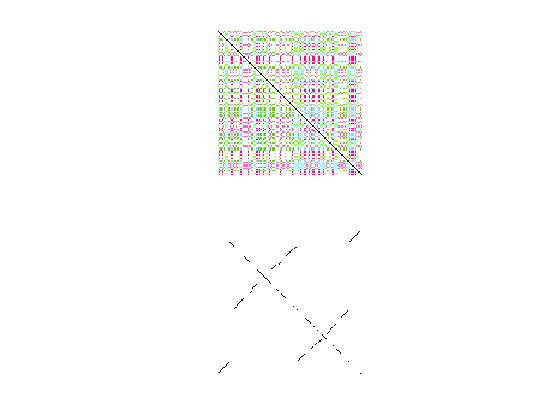

ex = 2;
if true
     figure('Name','Test con Immagini');
     for i=1:esempi
        subplot(ex,esempi,i); 
            imshow(immagini(i).imgX);
        subplot(ex,esempi,i+esempi); 
            imshow(immagini(i).imgCompare);
        if(ex>=3)
            subplot(ex,esempi,i+2*esempi); 
                imshow(immagini(i).imgT);
        end
        if(ex>=4)
            subplot(ex,esempi,i+3*esempi); 
            imshow(immagini(i).imgY);
        end        
     end
end

clearvars esempi ex i immagini nRNA NTest randomized TTest XTest L cutTest maxNetTrainSize

# **FUNZIONI**

Funzione che trasforma la matrice di Input in una matrice RGB

function out = tensor2RGB(r)
            L = size(r,1);
            out = zeros(L,L,3,"uint8");
                    
            categorie = [0,0,0;
                         255,0,127;
                         255,102,178;
                         153,255,255;
                         153,204,255;
                         102,204,0;
                         153,255,51;
                         255,255,255
                        ];
           
             for i=1:L
                 for k=1:L
                     
                     if( r(i,k,1)==1 )
                         out(i,k,:) = categorie(8,:);
                     end
                     if( r(i,k,2)==1 )
                         out(i,k,:) = categorie(1,:);
                     end
                     if( r(i,k,3)==1 )
                         out(i,k,:) = categorie(2,:);
                     end
                     if( r(i,k,4)==1 )
                         out(i,k,:) = categorie(3,:);
                     end
                     if( r(i,k,5)==1 )
                         out(i,k,:) = categorie(4,:);
                     end
                     if( r(i,k,6)==1 )
                         out(i,k,:) = categorie(5,:);
                     end
                     if( r(i,k,7)==1 )
                         out(i,k,:) = categorie(6,:);
                     end
                     if( r(i,k,8)==1 )
                         out(i,k,:) = categorie(7,:);
                     end
                 end
             end  
end

Comparazione Output/TMatrix

function out = Y2T(Y,T)
            L = size(Y,1);
            out = ones(L,L,3,"uint8")*255;
                    
            categorie = [0,255,0; %1 Verde
                         255,0,0; %2 Rosso
                         255,128,0; %3 Giallo
                         0,0,0; %4 Nero
                        ];
           
             for i=1:L
                 for k=1:L
                     %  Y corrisponde a T
                     if( Y(i,k,1)==0 && T(i,k,1)==0)
                         out(i,k,:) = categorie(4,:);
                     else
                         %  Y predetto ma sbagliato
                         if( Y(i,k,1)==0 && T(i,k,1)==1)
                             out(i,k,:) = categorie(2,:);
                         end
                         %  Y non predetto ma giusto
                         if( Y(i,k,1)==1 && T(i,k,1)==0)
                             out(i,k,:) = categorie(3,:);
                         end
                    end
                 end  
             end
end